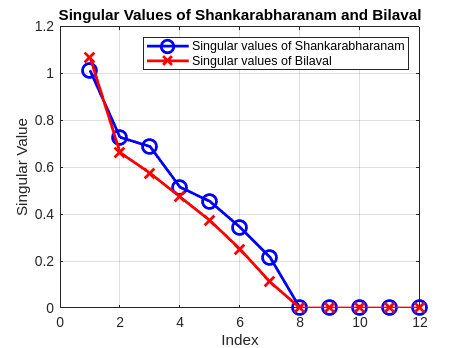

% Define Transition Probability Matrices (TPMs)
A = shankarabharanam_tpm; % Replace with your matrix (Shankarabharanam)
B = bilaval_tpm; % Replace with your matrix (Bilaval)

% Perform SVD on both matrices
[U_A, S_A, V_A] = svd(A);
[U_B, S_B, V_B] = svd(B);

% Extract Singular Values
singular_values_A = diag(S_A);
singular_values_B = diag(S_B);

% Plot Singular Values
figure;
plot(singular_values_A, 'bo-', 'MarkerSize', 10, 'LineWidth', 2); % Singular values of A
hold on;
plot(singular_values_B, 'rx-', 'MarkerSize', 10, 'LineWidth', 2); % Singular values of B
xlabel('Index');
ylabel('Singular Value');
title('Singular Values of Shankarabharanam and Bilaval');
legend('Singular values of Shankarabharanam', 'Singular values of Bilaval');
grid on;
hold off;


% Analyze Dominant Transition Patterns (First and Second Singular Vectors)
fprintf('--- Shankarabharanam Dominant Transition ---\n');

--- Shankarabharanam Dominant Transition ---



% First Singular Vector (dominant)
[~, max_uA_idx_1] = max(abs(U_A(:, 1))); % Find dominant starting note (u₁)
[~, max_vA_idx_1] = max(abs(V_A(:, 1))); % Find dominant ending note (v₁)

% Second Singular Vector (next dominant)
[~, max_uA_idx_2] = max(abs(U_A(:, 2))); % Find second dominant starting note (u₂)
[~, max_vA_idx_2] = max(abs(V_A(:, 2))); % Find second dominant ending note (v₂)

fprintf('Dominant Starting Note (u₁): Index %d\n', max_uA_idx_1);

Dominant Starting Note (u₁): Index 3


fprintf('Dominant Ending Note (v₁): Index %d\n', max_vA_idx_1);

Dominant Ending Note (v₁): Index 1


fprintf('Second Dominant Starting Note (u₂): Index %d\n', max_uA_idx_2);

Second Dominant Starting Note (u₂): Index 5


fprintf('Second Dominant Ending Note (v₂): Index %d\n', max_vA_idx_2);

Second Dominant Ending Note (v₂): Index 6



fprintf('\n--- Bilaval Dominant Transition ---\n');


--- Bilaval Dominant Transition ---



% First Singular Vector (dominant)
[~, max_uB_idx_1] = max(abs(U_B(:, 1))); % Find dominant starting note (u₁)
[~, max_vB_idx_1] = max(abs(V_B(:, 1))); % Find dominant ending note (v₁)

% Second Singular Vector (next dominant)
[~, max_uB_idx_2] = max(abs(U_B(:, 2))); % Find second dominant starting note (u₂)
[~, max_vB_idx_2] = max(abs(V_B(:, 2))); % Find second dominant ending note (v₂)

fprintf('Dominant Starting Note (u₁): Index %d\n', max_uB_idx_1);

Dominant Starting Note (u₁): Index 3


fprintf('Dominant Ending Note (v₁): Index %d\n', max_vB_idx_1);

Dominant Ending Note (v₁): Index 5


fprintf('Second Dominant Starting Note (u₂): Index %d\n', max_uB_idx_2);

Second Dominant Starting Note (u₂): Index 3


fprintf('Second Dominant Ending Note (v₂): Index %d\n', max_vB_idx_2);

Second Dominant Ending Note (v₂): Index 1



% Display Singular Values
disp('--- Singular Values ---');

--- Singular Values ---


disp('Shankarabharanam Singular Values:');

Shankarabharanam Singular Values:


disp(singular_values_A);

    1.0116
    0.7265
    0.6872
    0.5144
    0.4534
    0.3438
    0.2163
    0.0000
    0.0000
    0.0000
    0.0000
         0



disp('Bilaval Singular Values:');

Bilaval Singular Values:


disp(singular_values_B);

    1.0679
    0.6617
    0.5740
    0.4730
    0.3721
    0.2505
    0.1111
    0.0000
    0.0000
    0.0000
    0.0000
         0




% Optional: Display Full Singular Vectors for Inspection
disp('--- Left Singular Vector (u₁) for Shankarabharanam: ---');

--- Left Singular Vector (u₁) for Shankarabharanam: ---


disp(U_A(:,1));

   -0.3392
         0
   -0.4281
         0
   -0.3185
   -0.3961
         0
   -0.3441
         0
   -0.3797
         0
   -0.4252



disp('--- Right Singular Vector (v₁) for Shankarabharanam: ---');

--- Right Singular Vector (v₁) for Shankarabharanam: ---


disp(V_A(:,1));

   -0.4834
   -0.0000
   -0.2596
    0.0000
   -0.4071
   -0.3357
         0
   -0.4333
         0
   -0.3256
         0
   -0.3560




disp('--- Left Singular Vector (u₂) for Shankarabharanam: ---');

--- Left Singular Vector (u₂) for Shankarabharanam: ---


disp(U_A(:,2));

   -0.0915
   -0.0000
    0.3453
   -0.0000
   -0.7429
    0.2690
         0
   -0.4088
         0
    0.2472
         0
    0.1413



disp('--- Right Singular Vector (v₂) for Shankarabharanam: ---');

--- Right Singular Vector (v₂) for Shankarabharanam: ---


disp(V_A(:,2));

    0.1850
    0.0000
   -0.3540
         0
    0.3120
   -0.7668
         0
    0.2970
         0
   -0.1851
         0
    0.1809




disp('--- Left Singular Vector (u₁) for Bilaval: ---');

--- Left Singular Vector (u₁) for Bilaval: ---


disp(U_B(:,1));

   -0.3939
         0
   -0.4721
         0
   -0.3024
   -0.4692
         0
   -0.2504
         0
   -0.3868
         0
   -0.3131



disp('--- Right Singular Vector (v₁) for Bilaval: ---');

--- Right Singular Vector (v₁) for Bilaval: ---


disp(V_B(:,1));

   -0.4549
         0
   -0.2245
   -0.0000
   -0.6258
   -0.1491
         0
   -0.3435
         0
   -0.2257
         0
   -0.3998




disp('--- Left Singular Vector (u₂) for Bilaval: ---');

--- Left Singular Vector (u₂) for Bilaval: ---


disp(U_B(:,2));

   -0.0930
         0
    0.6946
         0
   -0.2595
   -0.1421
         0
   -0.2288
         0
   -0.5041
         0
    0.3391



disp('--- Right Singular Vector (v₂) for Bilaval: ---');

--- Right Singular Vector (v₂) for Bilaval: ---


disp(V_B(:,2));

    0.7896
   -0.0000
   -0.1232
         0
   -0.0378
   -0.2120
         0
   -0.3622
         0
    0.0749
         0
   -0.4222

